# Math420 - Group Homework 6

Authors: Robert 'Eddie' Bull, 

% First, establish R
sympref('TypesetOutput','default');
R=readmatrix('Nodes1thru57_dist_exact.txt');
S = R.^2;
n = size(R, 1)

n = 57


% Use Algorithm 1 to create Gram G
rho = (1/(2 * n)) * sum(sum(S))

rho = 4.4414e+07

upsilon = (1/n) *  (S - rho*eye(n)) * ones(n, 1)

upsilon = 1.0e+06 *

    0.3790
    0.5140
    0.8659
    0.3969
    0.6971
    1.6252
    0.6709
    0.6263
    0.0818
    0.1935


G = 0.5*upsilon*ones(n, 1)' + 0.5*ones(n, 1)*upsilon' - 0.5*S

G = 1.0e+06 *

    0.3790    0.2326    0.5616    0.1311   -0.1867    0.7848    0.4991   -0.4169    0.1647    0.2595    0.3817    0.3158   -0.2817   -0.4464   -0.0388    0.3384    0.1353    0.2476    0.5607   -0.5613   -0.2864    0.2003   -0.0206    0.3056   -0.0256   -0.1091    0.3050   -0.0805   -1.1033    0.2075    0.0126    0.1588    0.0071    0.1537   -0.0452    0.6744   -0.1275    0.0948    0.6176   -0.8758   -0.2258    0.4342   -0.9830    0.4886    0.0542   -0.6890   -1.1674   -0.8912   -0.7210    0.0847
    0.2326    0.5140    0.4566    0.4418   -0.5886    0.4729    0.2353   -0.5054    0.0395    0.2359    0.2130    0.2370    0.1088   -0.4421   -0.1335    0.1411    0.2177    0.1446    0.4040   -0.9835    0.2626    0.1699    0.3822    0.7392    0.0345   -0.0640    0.1087    0.2125   -0.7579    0.2493    0.2647   -0.0373   -0.2681    0.3247    0.4768    0.4927   -0.2032    0.0318    0.4726   -0.4778   -0.4903    0.2939   -1.3498    0.6060    0.1106   -0.7713   -1.0756   -1.3862   -


% Obtain eigenvalues of G
[Q, V] = eig(G)

Q =    -0.1178    0.1770   -0.0277   -0.0597    0.1686   -0.2430    0.0399    0.0692    0.2599   -0.0151   -0.0736   -0.0553   -0.2166    0.1419    0.1061    0.0318   -0.2414    0.0020   -0.0497   -0.0455    0.0146    0.1141    0.1439    0.0630   -0.1024    0.0789    0.0641    0.0191   -0.1325    0.0904    0.1074   -0.0542    0.1771    0.1336    0.1236   -0.0999    0.1915    0.0206   -0.1381   -0.0294   -0.2396    0.0575    0.3769    0.0077   -0.0511   -0.3433    0.1150    0.0759    0.0677    0.0582
    0.2019   -0.1063    0.0011    0.0394   -0.1269   -0.0168    0.1208    0.0411   -0.0786    0.0301    0.0280    0.0419   -0.1061    0.2657    0.0031   -0.1703    0.1502   -0.0398    0.3597    0.1595    0.0947    0.0413    0.1760    0.1900   -0.2792    0.2034    0.0813    0.0777   -0.1325    0.0626   -0.1119   -0.0647   -0.0240   -0.1979    0.1104   -0.0476    0.0795   -0.0751   -0.0390    0.0462   -0.0397   -0.2191   -0.1662    0.1198    0.0441   -0.2447   -0.1180   -0.0127    0.1039    0

V = 1.0e+07 *

   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

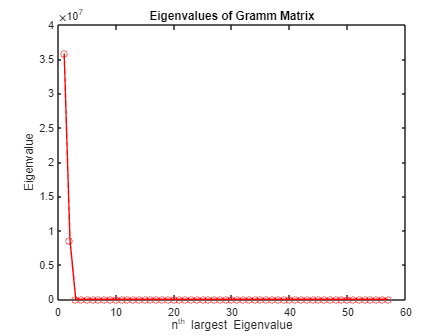

% Get the order index from the sort method
[E_G, order] = sort(diag(V), 'descend');
% Resort the Q and V to descending order
Q = Q(:, order);
V = V(order, order);

% Plot the Eigenvalues of the Gram Matrix
figure
plot(E_G, 'ro-')
title('Eigenvalues of Gram Matrix')
ylabel('Eigenvalue')
xlabel('n^{th} largest Eigenvalue')



E_G(1:10)

ans = 1.0e+07 *

    3.5808
    0.8605
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


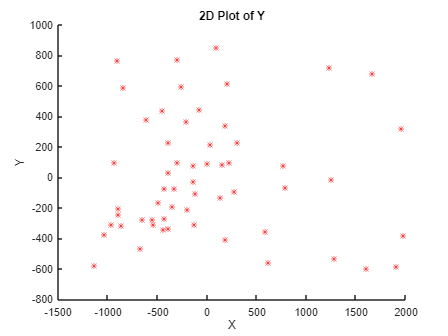

R - R_hat norm for d = 2 is: 5.3218e-06


Epsilon for d = 2 is: 0.018329


Little Sigma for d = 2 is: 0.018329


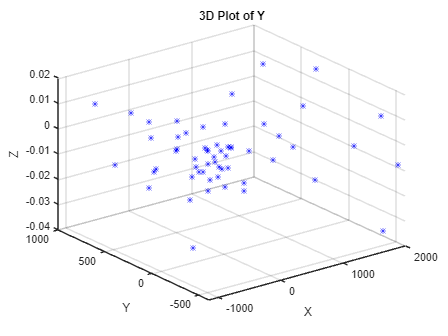

R - R_hat norm for d = 3 is: 1.3649e-05


Epsilon for d = 3 is: 0.017528


Little Sigma for d = 3 is: 0.017528


for j=[2 3]
    % Create a Q for the smaller dimensions
    Q_j = Q(:, 1:j);
    V_j = V(1:j, 1:j);

    % Compute the Y matrix for each dimension
    Y = V_j.^0.5 * Q_j';
    % When d = 2, it's easier to just plot the function with scatter
    % instead of scatter 3, so condition based on that.
    if j == 2
        figure
        % Scatters the X and Y value of the Y matrix.
        scatter(Y(1, :), Y(2, :), 'r*')
        title('2D Plot of Y')
        ylabel('Y')
        xlabel('X')
    else
        figure
        % Scatters the X, Y, and new Z of Y.
        scatter3(Y(1, :), Y(2, :), Y(3, :), 'b*')
        title('3D Plot of Y')
        ylabel('Y')
        xlabel('X')
        zlabel('Z')
    end
    
    % Pre-allocate for R_hat to increase speed.
    R_hat = zeros(n, n);
    for a = 1:n
        for b = 1:n 
            % Calculating R_hat based on the Algorithm 2
            R_hat(a, b) = norm(Y(:, a) - Y(:, b), 2);
        end
    end

    % Printing out important values
    disp('R - R_hat norm for d = ' + string(j) + ' is: ' + string(norm(R - R_hat, 2)))
    disp('Epsilon for d = ' + string(j) + ' is: ' + norm(G - Y' * Y, 'fro'))
    disp('Little Sigma for d = ' + string(j) + ' is: ' + sqrt(sum(E_G(j+1:n).^2)))
end

What's interesting is that the epsilon is equal to the little sigma value. This does make sense, though, as we're losing out on the data we aren't calculating, and the Frobenius norm is calculated in a similar way to how we found little sigma.